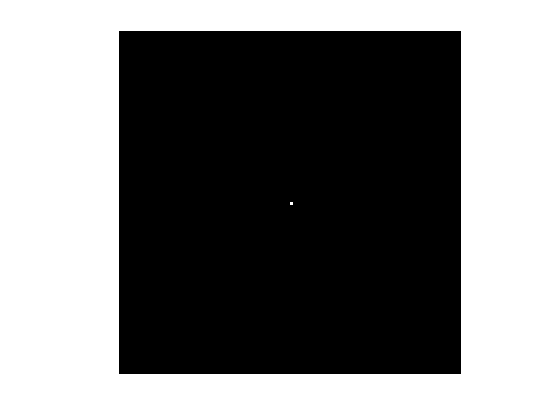

clear

pic=deltafcn(128,128);
%pic=phonecalc128;
showgrey(pic)

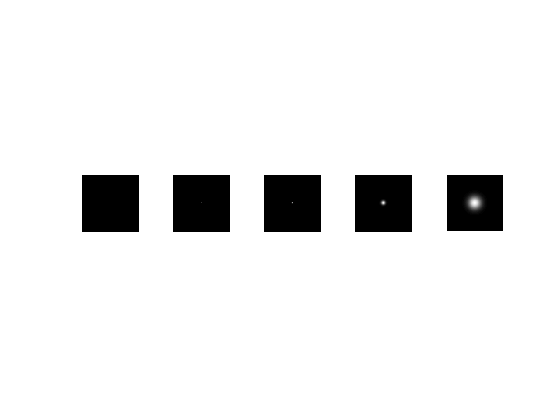

var =     0.0133   -0.0000
   -0.0000    0.0133


var =     0.2811    0.0000
    0.0000    0.2811


var =     1.0000   -0.0000
   -0.0000    1.0000


var =    10.0000   -0.0000
   -0.0000   10.0000


var =   100.0000   -0.0000
   -0.0000  100.0000



t=[0.1;0.3;1.0;10.0;100.0];

figure
for i=1:5
    psf=gaussfft(pic,t(i));
    var=variance(psf)

subplot(1,5,i)
showgrey(psf)
end

plot3(psf)


function psf=gaussfft(pic,t)
    
f=pic;

[xsize,ysize]=size(f);

g=zeros(xsize,ysize);
%[x,y]=meshgrid([0,xsize],[0,ysize]);
for x=1:xsize
    for y=1:ysize        
       g(x,y)=exp(-((x-xsize/2)^2+(y-ysize/2)^2)/(2*t))/(2*pi*t);
    end
end

F=fft2(f);
G=fft2(g);

FG=F.*G;
fg=ifft2(FG);

psf=fftshift(fg);
end